## 1/3)

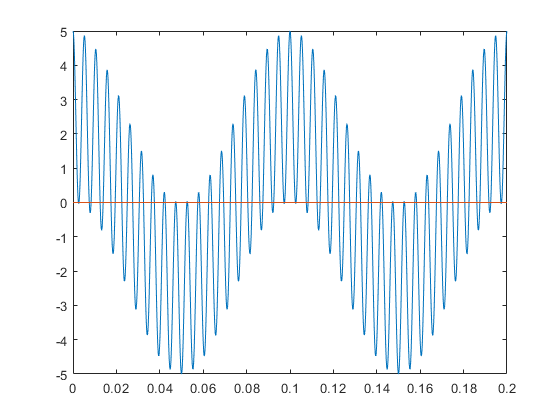

fs=48000; f1=90; f2=100; a1=5; a2=1;
[y3,prom]= multiCOS(f1,f2,fs,a1,a2);
axis([0 0.2 -5 5])

## 2/3)

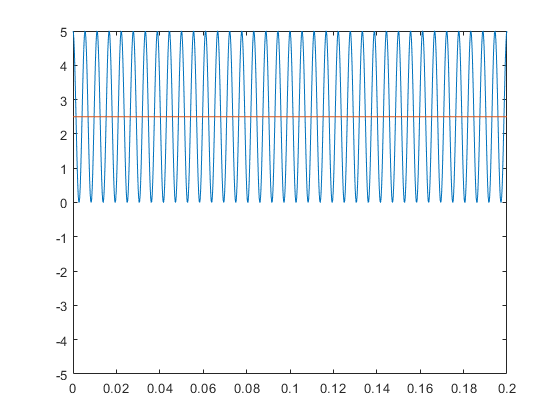

fs=48000; f1=90; f2=90; a1=5; a2=1;
[y3,prom]= multiCOS(f1,f2,fs,a1,a2);
axis([0 0.2 -5 5])

## 4) opcion probando

[ax,fx]=promCOS(y4,fs); % fx seria al frecuencia incognita, ax la amplitud

fx = 3

ax = 5.0000

## 5) opcion probando 

[ax,fx,axg]=promCOS(y5,fs);

fx = 900

ax = 10.0000

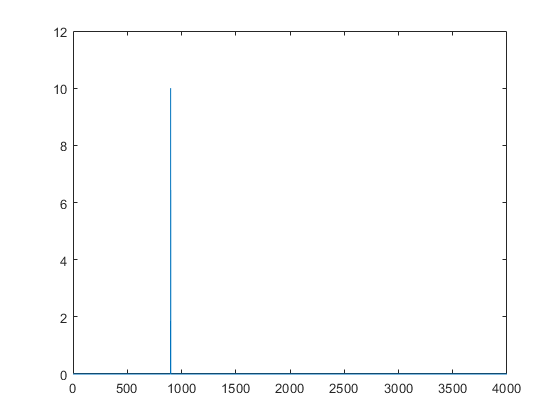

plot(axg)

## 6) opcion probando

[ax,fx,axg]=promCOS(y6,fs); 

fx = 500

ax = 7.0000

fx = 900

ax = 10.0000

fx = 2600

ax = 5.0000

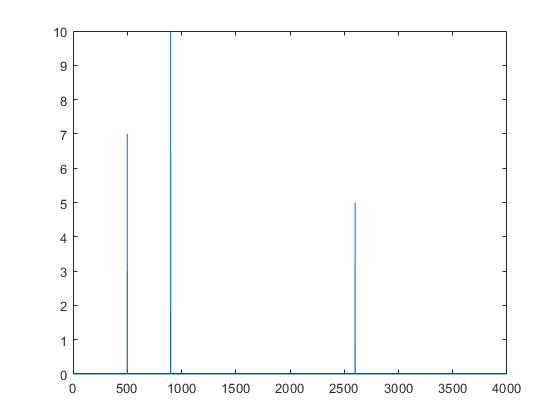

plot(axg)

## 4) opcion tp

for fn=1:6
    fn
    [PromedioN] = promedioDeCoseno(y4,fs,fn)
    amplitud=2*PromedioN
end

fn = 1

PromedioN = 0

amplitud = 0

fn = 2

PromedioN = 0

amplitud = 0

fn = 3

PromedioN = 2.5000

amplitud = 5.0000

fn = 4

PromedioN = 0

amplitud = 0

fn = 5

PromedioN = 0

amplitud = 0

fn = 6

PromedioN = 0

amplitud = 0

## 5) opcion tp

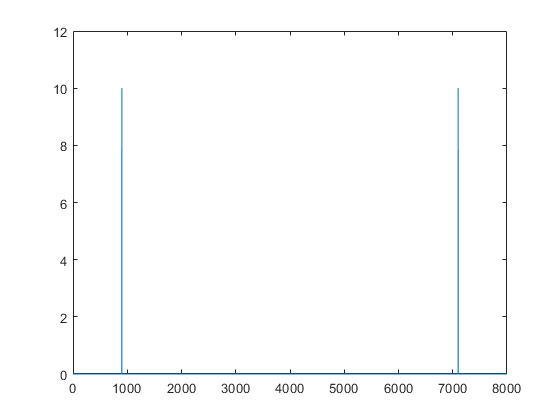

AmplitudComponentes=0:fs-1;
for fn=1:fs
    [AmplitudComponentes(fn)]=2*promedioDeCoseno(y5,fs,fn);    
end
plot(AmplitudComponentes)

## 6) opcion tp

AmplitudComponentes=0:fs-1;
for fn=1:fs
    [AmplitudComponentes(fn)]=2*promedioDeCoseno(y6,fs,fn);    
end
plot(AmplitudComponentes)
axis([0 fs/2 -inf inf])

## 7)

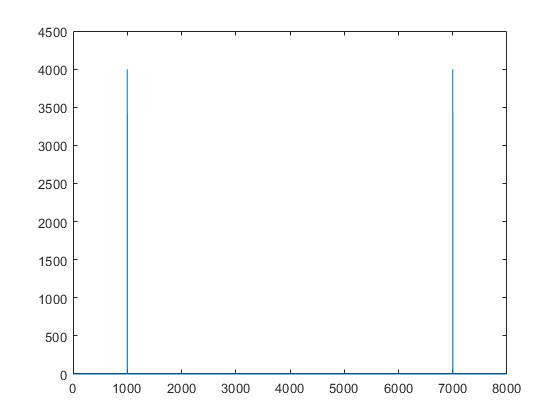

fs=8e3; dt=fs^-1;
t=0:dt:(fs-1)*dt;
y1=cos(2*pi*1e3*t);
Y1=fft(y1);
plot(abs(Y1))

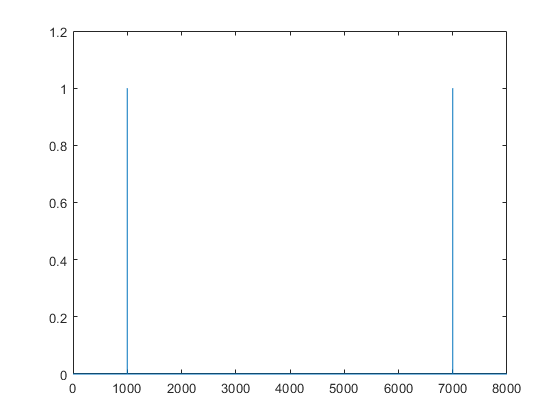

AmplitudFourier=abs(Y1)/length(Y1)*2;
longitud=length(y1);
f=(0:longitud-1)/longitud*fs;
plot(f,AmplitudFourier)

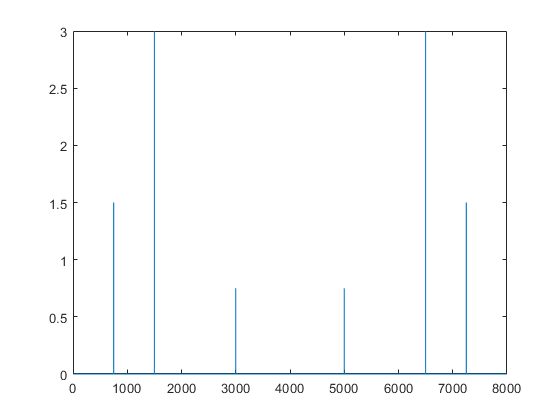

y2=3*cos(2*pi*1.5e3*t)+1.5*cos(2*pi*750*t)+0.75*cos(2*pi*3e3*t);
longitud=length(y2);
Y2=fft(y2);
AmplitudFourier=abs(Y2)/length(Y2)*2;
f=(0:longitud-1)/longitud*fs;
plot(f,AmplitudFourier)

## 8) El problema de detectar solamente componentes coseno

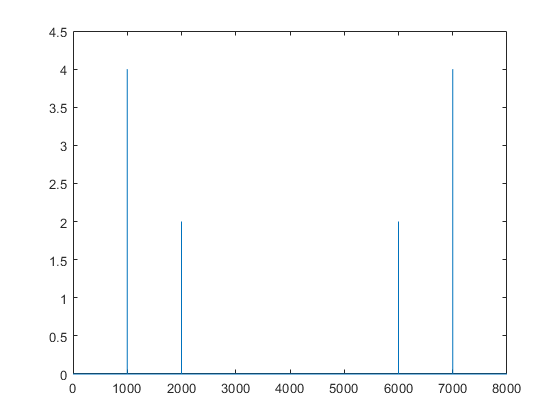

fs=8e3; t=0:(fs^-1):(fs-1)*(fs^-1);
y=4*cos(2*pi*1000*t)+2*sin(2*pi*2000*t);
AmplitudComponentes=0:fs-1;
for fn=1:fs
    [AmplitudComponentes(fn)]=2*promedioDeCoseno(y,fs,fn);    
end
Y=fft(y);
longitud=length(y);
AmplitudFourier=abs(Y)/length(Y)*2;
f=(0:longitud-1)/longitud*fs;
plot(f,AmplitudFourier)

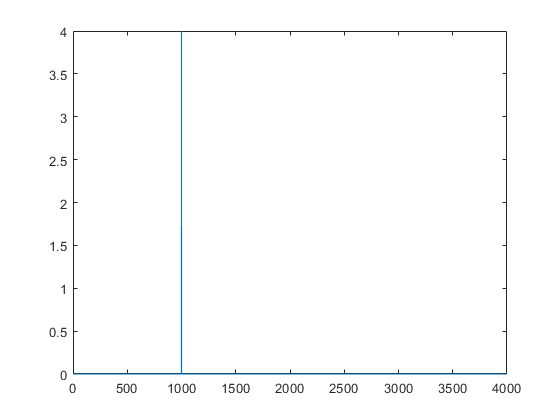

plot(AmplitudComponentes)
axis([0 fs/2 -inf inf])

## 9)  Función para detectar componentes seno

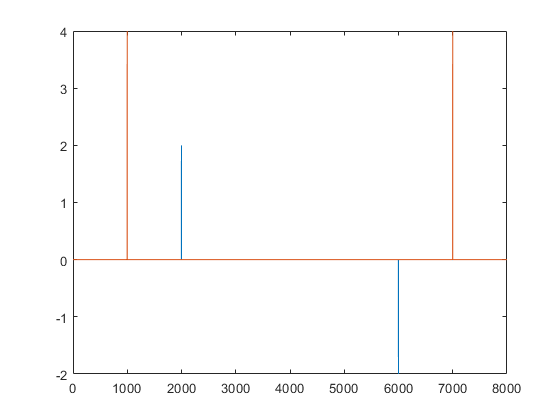

fs=8e3; t=0:(fs^-1):(fs-1)*(fs^-1);
y=4*cos(2*pi*1000*t)+2*sin(2*pi*2000*t);

AmplitudSeno=0:fs-1;
AmplitudCoseno=0:fs-1;
for fn=1:fs
    [AmplitudSeno(fn)]=2*promedioDeSeno(y,fs,fn);    
    [AmplitudCoseno(fn)]=2*promedioDeCoseno(y,fs,fn);   
end
f=(0:fs-1);
plot(f,AmplitudSeno,f,AmplitudCoseno)
axis([0 fs -inf inf]) 

## 10) Análisis de componentes con distintas fases

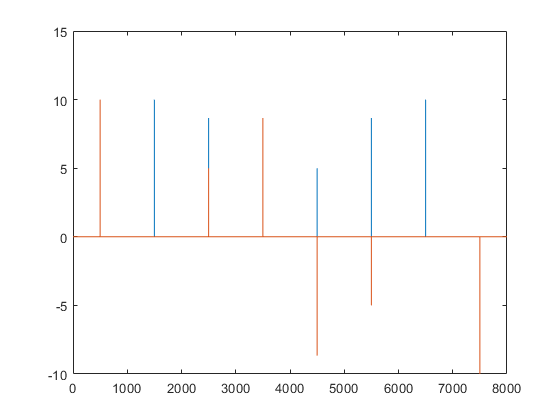

fs=8e3; dt=1/fs; f=(0:fs-1);
t=0:dt:(fs-1)*dt;
y= 10*sin(2*pi*500*t) + 10*sin(2*pi*1500*t + pi/2) + 10*sin(2*pi*2500*t + pi/3) + 10*sin(2*pi*3500*t + pi/6);

[Asen] = AmplitudSEN(y,fs);
[Acos] = AmplitudCOS(y,fs);

plot(f,Acos,f,Asen)

**f1 = **500 **    A1coseno =**0         **A1seno =**10

**f2 =**1500 **   A2coseno =**10      **A2seno =**0

**f3 =**2500**    A3coseno =**8.66   **A3seno =**5

**f4 =**3500  **  A4coseno =**0         **A4seno =**8.66

A500=sqrt(Acos(500+1)^2+Asen(500+1)^2)

A500 = 10.0000

A1500=sqrt(Acos(1500+1)^2+Asen(1500+1)^2)

A1500 = 10.0000

A2500=sqrt(Acos(2500+1)^2+Asen(2500+1)^2)

A2500 = 10.0000

A3500=sqrt(Acos(3500+1)^2+Asen(3500+1)^2)

A3500 = 10.0000

**FASES**

A500=atand(Asen(500+1)/Acos(500+1))

A500 = 90

A1500=atand(Asen(1500+1)/Acos(1500+1))

A1500 = 0

A2500=atand(Asen(2500+1)/Acos(2500+1))

A2500 = 30.0000

A3500=atand(Asen(3500+1)/Acos(3500+1))

A3500 = 60.0000

**f1 = **500 **    A1 =**10      **φ1 =**90

**f2 =**1500 **   A2 =**10      **φ2=**0

**f3 =**2500**    A3 =**10      **φ3 =**30

**f4 =**3500  **  A4 =**10      **φ4 =**60

**11) Función espectro()**

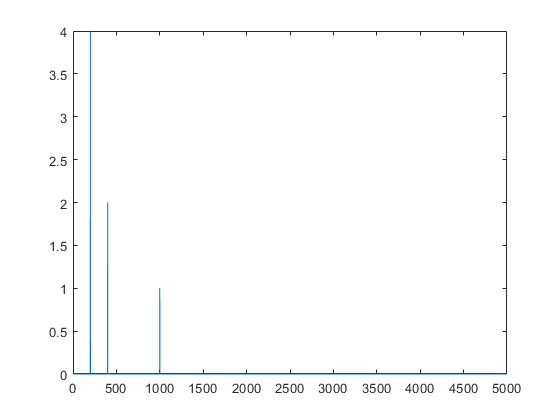

fs=10e3; dt=1/fs;
t=0:dt:1-dt;
y= 4*sin(2*pi*200*t)+2*sin(2*pi*400*t+pi/2)+sin(2*pi*1e3*t+pi);

tf=espectro(y);

plot(tf)
axis([0 fs/2 -inf 4])